# Simulazione Veicolo Autobilanciato - gruppo Calegari

## Setup iniziale dell'ambiente

clear
clc
digits(4)

%load('WS_VAB_wb_0.mat','A','B','C','D','r');
load('WS_VAB_wb_0_5.mat','A','B','C','D','r','J_r');

## Sensori

sensitivity_giroscopio = 131*180/pi;%[s/rad]
sensitivity_encoder = 2048;%
sensitivity_arduino = 2^10;

## Costanti del motore

Definizione delle costanti necessarie alla modellizzazione del comportamento del motore.

k_t = 0.1; % Costante di coppia [Nm/A]
R = 0.13; % Resistenza interna del motore[ohm]
L = 0.10e-3; % Induttanza del motore [H]
tau_e = 1.22*10^-3; % Costante di tempo elettrica [m]
tau = 0.1*22/26; % Rapporto di trasmissione
J_m_star = 3.7e-4+double(J_r)*tau^2; %Inerzia del motore ridotta all'albero [kg m^2]
I_max = 20;
C_max = 20*k_t;
fc=1000;
wc=2*pi*fc;
ti_i = tau_e;
kg_i = wc*tau_e*R; 
PI_I = kg_i*tf([ti_i,1],[ti_i,0])
PI_I_coeff = (kg_i*[ti_i,1])./(kg_i*[ti_i])
P = PI_I_coeff(1)
I = PI_I_coeff(2)
motor_selection = 1;

## Modellizzazione del motore

Il primo parametro che andiamo a definire rappresenta l'inerzia del rotore ridotta allìalbero motore.

Per costruzione, è presente una trasmissione a cinghia che presenta un passo 8: essendo il passo uguale per entrambe le pulegge, si ha che l'effettivo diametro delle pulegge stesse, nel calcolo del rapporto di trasmissione, viene a cadere, e quindi risulta essere sufficiente andare ad effettuare il rapporto tra il numero di denti delle pulegge:

 
$$\tau =\frac{n_{\textrm{in}\;} }{n_{\textrm{out}} }$$


tau = 0.1*22/26;
J_rotore = double(J_r) * tau^2;
Ts = 0.0001;
showBode = false;
motor = ConfigDCMotor(1, J_rotore, showBode)
currentClosedLoop = CurrentLoop(motor, showBode, Ts)
motor_selection = 0;

## Analisi stabilità e discretizzazione

A_real = double(A);
B_real = double(B);
C_real = double(C);
D_real = double(D);

states = {'phi' 'phi_dot' 'theta' 'theta_dot'};
inputs = {'Cm'};
outputs = {'phi' 'phi_dot' 'theta' 'theta_dot'};
sys = ss(A_real,B_real,C_real,D_real,'statename',states,'inputname',inputs,'outputname',outputs); % Same of G
sys_d = c2d(sys,Ts, 'tustin')
A_d = sys_d.a;
B_d = sys_d.b;
C_d = sys_d.c;
D_d = sys_d.d;

## Analisi grafiche

eig(A_d)

Come si vede il sistema non è asintoticamente per la presenza di autovalori esterni al cerchio unitario.

Questo è confermato anche dalla presenza di poli all'esterno del cerchio unitario.

pzmap(sys_d)
M_r = ctrb(sys_d); % Matrice di raggiungibilità
rank(M_r)
M_o = obsv(sys_d); % Matrice di osservabilità
rank(M_o)

Questo mette in evidenza come il nostro sistema discreto sia completamente controllabile e osservabile, per il fatto che il rango delle matrici sia pari alla dimensione del vettore di stato.

## Posizionamento dei poli discreti

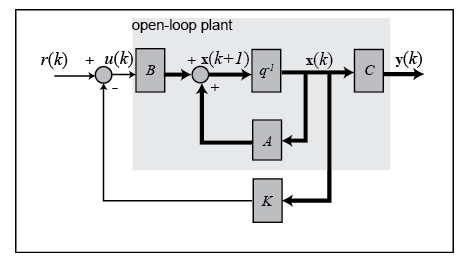

syms xsi wn1 wn2 s;
dd_1 = s^2 + s * 2 * xsi * wn1 + wn1^2 == 0;
dd_2 = s^2 + s * 2 * xsi * wn2 + wn2^2 == 0;
sol_dd_1 = solve(dd_1, s);
sol_dd_2 = solve(dd_2, s);

Definisco la pulsazione naturale per primo polo, destinato al controllo più veloce per l'angolo $\theta \;\ldotp$

% fn1 = 20; % [Hz]
fn1 = 0.2; % [Hz]
w1 = 2*pi*fn1; % [rad / s]

Definisco i parametri anche per il secondo polo, invece più lento e destinato a $\phi \;\ldotp$

% fn2 = 2; % [Hz]
fn2 = 0.02; % [Hz]
w2 = 2*pi*fn2; % [rad / s]

Definisco anche lo smorzamento per i poli

e =0.7; % Smorzamento

Sostituisco i parametri numeri di pulsazione e smorzamento nelle soluzione dei poli:

pol_1 = subs(sol_dd_1,{xsi,wn1},{e,w1});
pol_2 = subs(sol_dd_2,{xsi,wn2},{e,w2});
pol_1_continuos = double(pol_1)
pol_2_continuos = double(pol_2)

pol_3_continuos = real(pol_2_continuos(1))/10

Spesso l'approccio che si segue è quello di andare a settare la posizione dei poli inizialmente nel dominio a tempo continuo e successivamente mappare

i poli setteti nel continuos-time domain nel discrete-time domain utilizzando


$$z=\exp \left(\textrm{sTs}\right)$$


poles_1_disc=exp(pol_1_continuos.* Ts);
poles_2_disc=exp(pol_2_continuos.* Ts);
poles_3_disc=exp(pol_3_continuos.* Ts);
K_d = place(A_d,B_d,[poles_1_disc', poles_2_disc'])
A_aug = [A_d,[0;0;0;0];[0,-1,0,0],1]
B_aug=[B_d,[0;0;0;0];0,1]
poles = [poles_1_disc', poles_2_disc',poles_3_disc]
K_aug = place(A_aug,B_aug,poles)
K_i = K_aug(2,5)

K_c = place(A_real,B_real,[pol_1_continuos', pol_2_continuos'])

Calcolo la nuova matrice A in anello chiuso con i valori di K:

A_cl = A_d - B_d * K_d;

Verifico che i nuovi autovalori abbiano parte reale negativa.

eig(A_cl)
sys_cl = ss(A_cl,B_d,[0,0,1,0],[0], Ts);
pzmap(sys_cl)

Posso utilizzare un'altra tecnica per realizzare il place dei poli (LQR - Regolatore Lineare Quadratico) che rappresenta una soluzione ottima per il pole placement:

Q = eye(4);
R = 1;
K_lqr_d = dlqr(A_d,B_d,Q,R)
A_cl_lqr_d = A_d - B_d * K_lqr_d;
sys_cl_lqr_d = ss(A_cl_lqr_d,B_d,[0,0,1,0],[0], Ts);
pzmap(sys_cl_lqr_d) 

## Simulazione

### Condizioni iniziali

% Initial condition for open loop model
x_0 = [0; 0; 4 * pi / 180; 0];
phi_iniziale = x_0(1);
phi_p_iniziale = x_0(2);
theta_iniziale = x_0(3);
theta_p_iniziale = x_0(4);
r_simulazione = double(r);
control_on = 1;
t_end = 5;
phi_p_setpoint = 10;
m_c_simulazione = double(70); % Vale solo nel non lineare
k_simulazione_discreta = K_d;

## Simulazione discreta

### Sistema lineare

disp('Closed loop');
disp('Linear discrete system');
simOut = sim('VAB_Linear_Discrete');
completeState = simOut.completeState;
out = simOut.Output;
thetaClamped = simOut.theta_Clamped;
phiClamped = simOut.phi_Clamped;
torqueRequested = simOut.torqueRequested;
actualTorque = simOut.actualTorque;
tout = simOut.tout;
posizione = phiClamped*r_simulazione;
discreteTime = 0:Ts:t_end;

figure
hold on
plot(tout, thetaClamped,'b')
xlabel('Time [s]')
yyaxis left
ylabel('Angles [°]')
yyaxis right
ylabel('Position[m]')
plot(tout, posizione)
legend('Theta','Posizione');
ax = gca;
ax.YAxis(1).Color = 'b';
title('Angle - linear discrete sys, closed loop')
hold off
figure
plot(discreteTime, [torqueRequested,actualTorque])
xlabel('Time [s]')
ylabel('Torque [N*m]')
title('Torque - linear discrete sys, closed loop')
legend('Coppia richiesta', 'Coppia erogata');
ylim([-3 3])
hold off
figure
hold on
plot(tout, completeState) 
xlabel('Time [s]')
ylabel('States')
title('Complete state - linear discrete sys, closed loop')
legend('phi', 'phi punto', 'theta', 'theta punto');
hold off
figure
plot(tout, [simOut.sensor_state])
xlabel('Time [s]')
title('Sensed state - linear discrete sys, closed loop')
legend('phi', 'phi punto', 'theta', 'theta punto');
hold off

## Sistema non lineare

disp('Non linear discrete system');
control_on = 1;
simOut = sim('VAB_non_linear_Discrete.slx');
completeState = simOut.completeState;
out = simOut.Output;
thetaClamped = simOut.theta_Clamped;
phiClamped = simOut.phi_Clamped;
torqueRequested = simOut.torqueRequested;
actualTorque = simOut.actualTorque;
tout = simOut.tout;
posizione = phiClamped*r_simulazione;

figure
hold on
plot(tout, thetaClamped,'b')
xlabel('Time [s]')
yyaxis left
ylabel('Angles [°]')
yyaxis right
ylabel('Position[m]')
plot(tout, posizione)
legend('Theta','Posizione');
ax = gca;
ax.YAxis(1).Color = 'b';
title('Angle - non linear discrete sys, closed loop')
figure
plot(discreteTime, [torqueRequested,actualTorque])
xlabel('Time [s]')
ylabel('Torque [N*m]')
title('Torque - non linear discrete sys, closed loop')
legend('Coppia richiesta', 'Coppia erogata');
hold off
figure
hold on
plot(tout, completeState)
xlabel('Time [s]')
ylabel('States')
title('Complete state - non linear discrete sys, closed loop')
legend('phi', 'phi punto', 'theta', 'theta punto');
hold off
clearvars ax

NB: State needs to be defined in rad!

%call_plot(completeState * pi / 180);